#### BME 4400 Vanderbilt University

#### Professor Mark D. Does

# Central Slice Theorem

See section 3.3.2.2 (Projection Slice Theorem) in Suetens

clear all
close all


load example_image

whos

  Name           Size              Bytes  Class     Attributes

  FOV            1x1                   8  double              
  IMG50        128x128            131072  double              
  x_index        1x128              1024  double              
  y_index        1x128              1024  double              



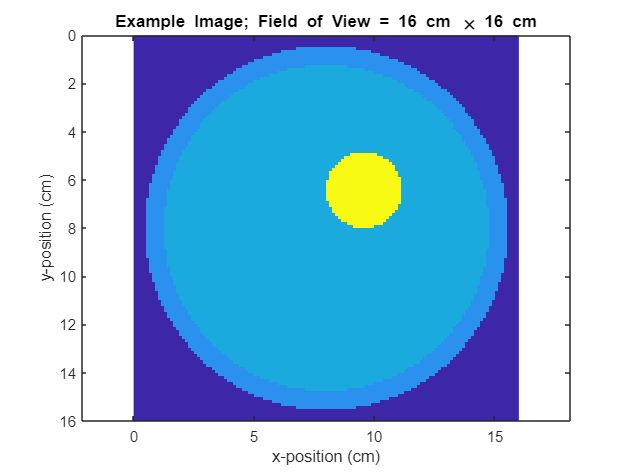


dy = diff(y_index(1:2)); % sample period in the y direction
dx = diff(x_index(1:2)); % sample period in the x direction
[Ny,Nx] = size(IMG50);

figure
imagesc(y_index,x_index,IMG50), axis equal
xlabel('x-position (cm)')
ylabel('y-position (cm)')
title(['Example Image; Field of View = ',num2str(FOV,2),...
    ' cm \times ',num2str(FOV,2),' cm'])

Use this image to demonstrate Central Slice Theorem (aka, Projection Slice Theorem, aka, Fourier Slice Theorem).

Central Slice Theorem states that the 1DFT of a projection, $p(r,\theta)$, through

an image, $\mu(x,y)$, is equal to a line (a *slice*) through the 2DFT of the image. That is, given


$$M(k_\mathrm{x},k_\mathrm{y}) = \int_{-\infty}^\infty \int_{-\infty}^\infty dx \, dy\; \mu(x,y) \exp\left[-i2 \pi \left(x k_\mathrm{x} + y k_\mathrm{y}\right)\right]$$
 

and


$$p(r,\theta) = -\log\left[\frac{I(r,\theta)}{I_0}\right] =  -\int_{-\infty}^\infty ds \, µ(r\cos \theta -s \sin \theta,r \sin \theta + s \cos \theta)$$



$$P(k,\theta) = \int_{-\infty}^\infty dr \; p(r,\theta) \exp\left[-i2 \pi r k]$$


then 

$P(k,\theta)$ is a line through $M(k_\mathrm{x},k_\mathrm{y})$, as shown in the figure below.

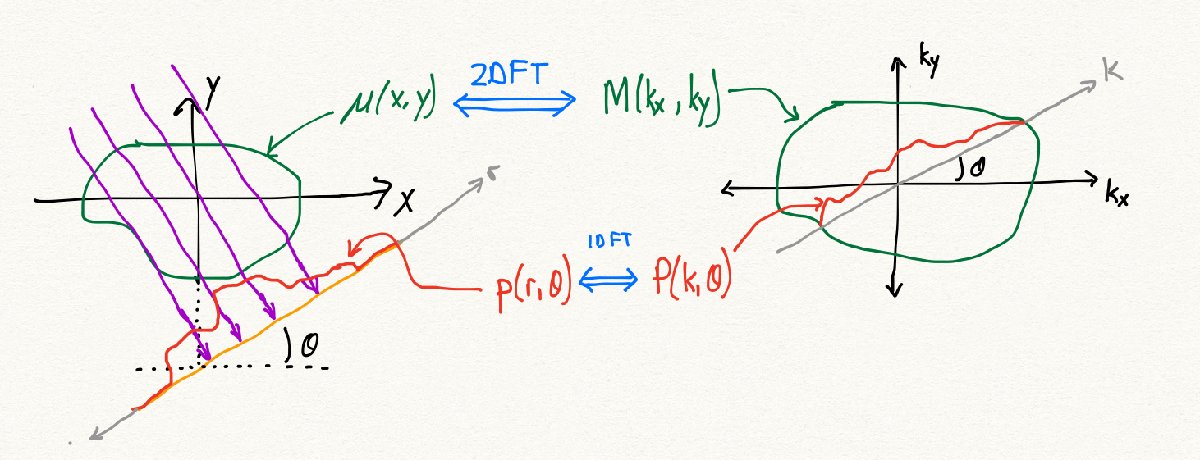

Central Slice theorem: Doing 2D FFT of u(x,y) to M(kx, ky) is equal to doing 1D FFT of a projection  [a line in Fourier domain]

To demonstrate this theorem, consider a projection through image IMG50 at angle $\theta = 0^\circ$ -- i.e.,** projecting along the column**s. To compute this, we integrate the signal along each column -- we can use trapazoidal approximation for integration -- and then we compute the 1D FT.


% projection in vertical (theta = 0°) direction is dimension 1
p_0 = trapz(y_index, IMG50, 1);

%We now take the fft of this projection.
P_0 = dy*fftshift(fft(p_0)); %eq. 3.13 from text --- 1D FT of projection

dk = 1./(Ny*dy);
k = (-1/2/dy:dk:(1/2/dy-dk))';

figure('Name','A3: Problem 2. Projection at theta = 0°')
semilogy(k,abs(P_0),'r-')
xlabel('k (cm^{-1})')
ylabel('P(k,\theta=0')
hold on

Now let us compare this to the **slice through the 2DFT of IMG50**. With $\theta = 0$, the slice in $M(k_\mathrm{x},k_\mathrm{y})$ corresponds to the central *row* through the 2DFT of IMG50 (which is the $N_y/2+1$row).

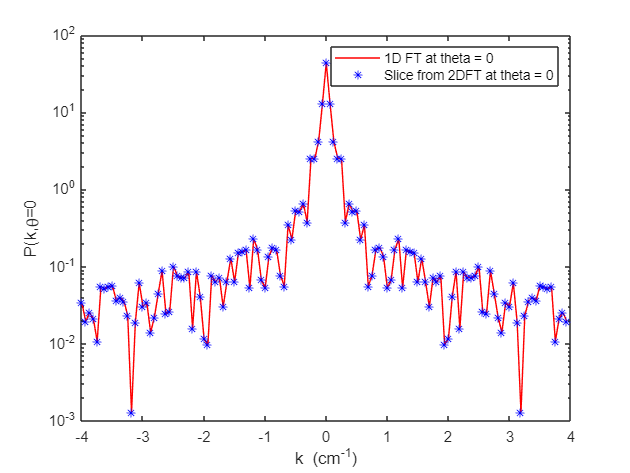

M = dx*dy*fftshift(fft2(IMG50)); % intergral dx in FFT --> add deltaX in MATLAB fft
M_0 = M(Ny/2+1,:);
semilogy(k,abs(M_0),'b*')
legend('1D FT at theta = 0', 'Slice from 2DFT at theta = 0')

They agree, thus demontrasting the Central Slice Theorem. 

To reconstruct the full image from a sinogram without backprojecting we can perform** 1D FT on each projection** in the sinogram, to produce a radial sampling of $M(k_\mathrm{x},k_\mathrm{y})$. We then need to **"grid" these sample**s -- i.e., interpolate the radial samples onto a Cartesian grid -- then inverse 2D FT to get the reconstructed image. 

Because there is no backprojection process, there is no filtering to correct for the blurring imparted by backprojecting.